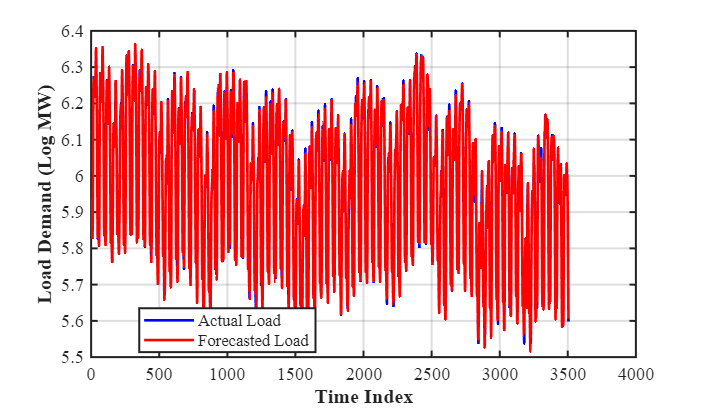

clc; clear; close all;

%% =====================================================
% ANN LOAD FORECASTING MODEL
% (CONFERENCE PAPER VERSION)
% Includes:
% 1. Actual vs Forecast Plot
% 2. Zoom Plot
% 3. MAPE vs Horizon Plot
% 4. PNG Export (600 DPI)
%% =====================================================

%% =========================
% LOAD DATA
%% =========================
data = readtable('data/Complete_datasheet.csv');

y = double(data.Log_MW);

% Clean data
y = fillmissing(y,'linear');
y = filloutliers(y,'linear');

T = length(y);

%% =========================
% PARAMETERS
%% =========================
lag = 48;          % previous 48 half-hours
hidden = 10;       % hidden neurons

%% =========================
% CREATE DATASET
%% =========================
X = [];
Y = [];

for t = lag+1:T
    X = [X, y(t-lag:t-1)];
    Y = [Y, y(t)];
end

N = size(X,2);

%% =========================
% TRAIN / TEST SPLIT
%% =========================
train_ratio = 0.80;
Ntrain = floor(train_ratio*N);

Xtrain = X(:,1:Ntrain);
Ytrain = Y(:,1:Ntrain);

Xtest  = X(:,Ntrain+1:end);
Ytest  = Y(:,Ntrain+1:end);

%% =========================
% TRAIN NETWORK
%% =========================
net = fitnet(hidden);

net.trainParam.showWindow = false;
net.trainParam.epochs = 200;

net = train(net,Xtrain,Ytrain);

%% =========================
% ONE-STEP TEST FORECAST
%% =========================
Y_pred_test = net(Xtest);

start_idx = lag + Ntrain + 1;

y_pred = nan(T,1);
y_pred(start_idx:end) = Y_pred_test';

valid = start_idx:T;

%% =====================================================
% FIGURE 1 : ACTUAL vs FORECAST
%% =====================================================
figure('Color','w','Position',[100 100 720 420]);

plot(y(valid),'b','LineWidth',1.6); hold on;
plot(y_pred(valid),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ANN_Actual_vs_Forecast.png','Resolution',600);

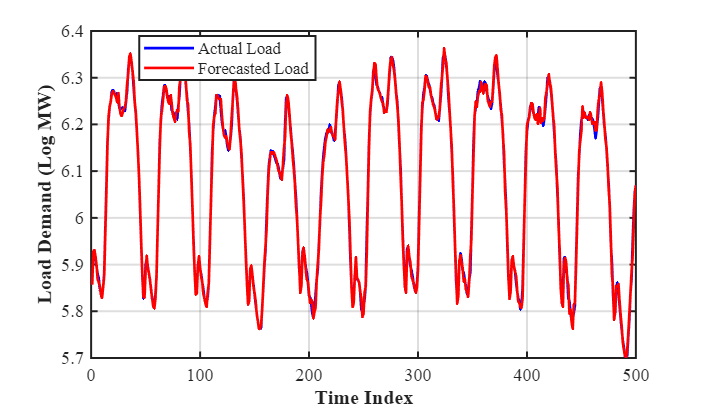


%% =====================================================
% FIGURE 2 : ZOOM VIEW
%% =====================================================
figure('Color','w','Position',[120 120 720 420]);

plot(y(valid(1:500)),'b','LineWidth',1.6); hold on;
plot(y_pred(valid(1:500)),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ANN_Zoom_View.png','Resolution',600);

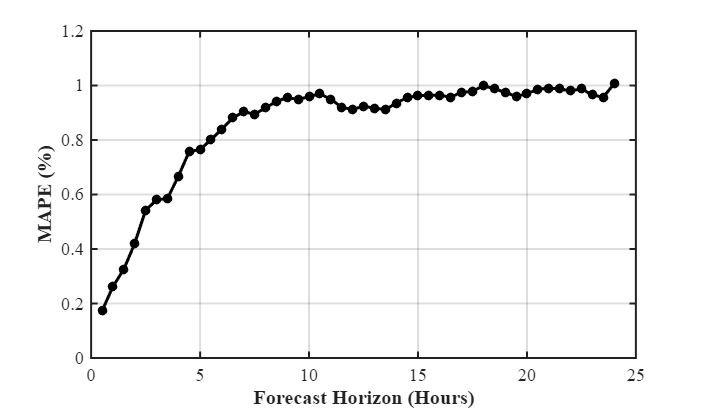


%% =========================
% FAST RECURSIVE MAPE
%% =========================
max_h = 48;
MAPE = zeros(max_h,1);

step = 20;   % speed-up

for t = start_idx:step:(T-max_h)
    
    input_seq = y(t-lag+1:t);
    preds = zeros(max_h,1);
    
    for k = 1:max_h
        
        y_next = net(input_seq);
        preds(k) = y_next;
        
        input_seq = [input_seq(2:end); y_next];
    end
    
    for h = 1:max_h
        
        y_hat = preds(h);
        y_true = y(t+h);
        
        if y_true ~= 0
            MAPE(h) = MAPE(h) + abs((y_true-y_hat)/y_true);
        end
    end
end

num_samples = length(start_idx:step:(T-max_h));
MAPE = (MAPE/num_samples)*100;

%% =====================================================
% FIGURE 3 : MAPE vs HORIZON
%% =====================================================
figure('Color','w','Position',[140 140 720 420]);

plot((1:max_h)/2,MAPE,'k-o',...
    'LineWidth',1.8,...
    'MarkerSize',4,...
    'MarkerFaceColor','k');

grid on;
box on;

xlabel('Forecast Horizon (Hours)',...
    'FontSize',12,'FontWeight','bold');

ylabel('MAPE (%)',...
    'FontSize',12,'FontWeight','bold');

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ANN_MAPE_vs_Horizon.png','Resolution',600);


%% =====================================================
% TABLE OUTPUT
%% =====================================================
horizon = (1:max_h)'/2;

MAPE_Table = table(horizon,MAPE,...
    'VariableNames',{'Horizon_Hours','MAPE_percent'});

disp(MAPE_Table);

    Horizon_Hours    MAPE_percent
    _____________    ____________

         0.5           0.17249   
           1           0.26228   
         1.5           0.32562   
           2            0.4205   
         2.5           0.54187   
           3           0.58043   
         3.5           0.58499   
           4           0.66641   
         4.5           0.75748   
           5           0.76512   
         5.5           0.80115   
           6           0.84009   
         6.5           0.88094   
           7           0.90439   
         7.5           0.89414   
           8           0.91785   
         8.5           0.94127   
           9           0.95636   
         9.5           0.94831   
          10           0.95988   
        10.5           0.96895   
          11           0.94995   
        11.5           0.91963   
          12           0.91244   
        12.5           0.92374   
          13 


writetable(MAPE_Table,'ANN_MAPE_Table.csv');

%% =====================================================
% ERROR METRICS
%% =====================================================
rmse = sqrt(mean((y(valid)-y_pred(valid)).^2));
mae  = mean(abs(y(valid)-y_pred(valid)));

fprintf('\nRMSE = %.4f\n',rmse);


RMSE = 0.0131


fprintf('MAE  = %.4f\n',mae);

MAE  = 0.0098



disp('Saved Files:');

Saved Files:


disp('1. ANN_Actual_vs_Forecast.png');

1. ANN_Actual_vs_Forecast.png


disp('2. ANN_Zoom_View.png');

2. ANN_Zoom_View.png


disp('3. ANN_MAPE_vs_Horizon.png');

3. ANN_MAPE_vs_Horizon.png


disp('4. ANN_MAPE_Table.csv');

4. ANN_MAPE_Table.csv
